%Calibration Voltage to force
Force_N_Cal = Force_Kg_Cal.*(9.81)

Force_N_Cal = 1.0e+04 *

    0.3012
    0.5906
    0.8839
    1.1811
    1.4715
    1.7678
    2.0630
    2.3544
    2.6497
    2.9567


[Cal_Parameters , gof_Cal] = fit(Voltage_Cal,Force_N_Cal,'poly1')

Cal_Parameters =      Linear model Poly1:
     Cal_Parameters(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   2.713e+04  (2.658e+04, 2.769e+04)
       p2 =       650.6  (300.3, 1001)

gof_Cal = struct with fields:
           sse: 8.3146e+05
       rsquare: 0.9991
           dfe: 11
    adjrsquare: 0.9990
          rmse: 274.9316


Gain_Cal = Cal_Parameters.p1

Gain_Cal = 2.7134e+04

offset_Cal = Cal_Parameters.p2

offset_Cal = 650.5614

%Calculated parameters, about 400N off accrdoing to lab view

%Getting Prediction interval and confidence
Deviation_Cal = gof_Cal.rmse

Deviation_Cal = 274.9316

U_cal = 2*Deviation_Cal %Used to get prediction

U_cal = 549.8632


Upper_Bound_Cal = Force_N_Cal+U_cal

Upper_Bound_Cal = 1.0e+04 *

    0.3562
    0.6455
    0.9389
    1.2361
    1.5265
    1.8228
    2.1180
    2.4094
    2.7047
    3.0117


Lower_Bound_Cal = Force_N_Cal-U_cal

Lower_Bound_Cal = 1.0e+04 *

    0.2462
    0.5356
    0.8289
    1.1261
    1.4165
    1.7129
    2.0081
    2.2994
    2.5947
    2.9017



conf_intercal_Difference = Gain_Cal-(2.769e+4) %Confidence INterval For gain

conf_intercal_Difference = -556.3263

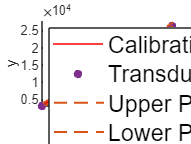


%Plotting model, data and prediction interval
figure
hold on
plot(Cal_Parameters)
plot(Voltage_Cal,Force_N_Cal,'.','Color',"#7E2F8E",'MarkerSize',15)
%PLotting PRediction interval
plot(Voltage_Cal,(Gain_Cal.*Voltage_Cal+offset_Cal+U_cal),'--','Color',"#D95319",'LineWidth',1.2)
plot(Voltage_Cal,(Gain_Cal.*Voltage_Cal+offset_Cal-U_cal),'--','Color',"#D95319",'LineWidth',1.2)
legend('Calibration Model','Transducer Data','Upper Prediction Interval','Lower Prediction Interval','Fontsize',14,'Location','northwest')
xlim([0.09 0.96])
ylim([3000 28000])

%Displacement sensor calibration was on .3mm

%Characterizing Rig Deformation
%Need to cut off when we stopped
[r,c]=size(Force_Rig_Def)

r = 13440

c = 1

[Max_Force, Max_Index] = max(Force_Rig_Def)

Max_Force = 32300

Max_Index = 7076

Cut_M = true(r,c)

Cut_M = 13440×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Cut_M(Max_Index+1:length(Cut_M),1) = false

Cut_M = 13440×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


CForce_Rig_Def = Force_Rig_Def(Cut_M)

CForce_Rig_Def = 1.0e+04 *

    0.0473
    0.0464
    0.0473
    0.0473
    0.0481
    0.0507
    0.0524
    0.0490
    0.0516
    0.0481


CPosition_Rig_Def = Position_Rig_Def(Cut_M)

CPosition_Rig_Def =    55.8000
   55.7800
   55.7800
   55.7600
   55.7400
   55.7400
   55.8000
   55.8200
   55.8600
   55.6500


CTime_Rig_Def = Time_Rig_Def(Cut_M)

CTime_Rig_Def =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450



%Trying different Fits
linearFit = fittype({'x'}); 
quadraticFit = fittype({'x^2','x'});

[Lin_Rig_fit, Lin_gof_Rig] = fit(CForce_Rig_Def,CPosition_Rig_Def,linearFit)

Lin_Rig_fit =      Linear model:
     Lin_Rig_fit(x) = a*x
     Coefficients (with 95% confidence bounds):
       a =    0.002369  (0.002331, 0.002407)

Lin_gof_Rig = struct with fields:
           sse: 8.5254e+06
       rsquare: -179.7554
           dfe: 7075
    adjrsquare: -179.7554
          rmse: 34.7132


RMSE_linear_mm = Lin_gof_Rig.rmse;

[Quad_Rig_Fit, Quad_gof_Rig] = fit(CForce_Rig_Def,CPosition_Rig_Def,quadraticFit)

Quad_Rig_Fit =      Linear model:
     Quad_Rig_Fit(x) = a*x^2 + b*x
     Coefficients (with 95% confidence bounds):
       a =  -1.517e-07  (-1.588e-07, -1.447e-07)
       b =    0.006635  (0.006434, 0.006836)

Quad_gof_Rig = struct with fields:
           sse: 6.8076e+06
       rsquare: -143.3340
           dfe: 7074
    adjrsquare: -143.3544
          rmse: 31.0216


U_rig_mm = 69.4264

Rig_fit_Data =     1.1192
    1.0989
    1.1192
    1.1192
    1.1398
    1.2012
    1.2422
    1.1602
    1.2218
    1.1398


Rig_Up_Bound =    70.5456
   70.5253
   70.5456
   70.5456
   70.5663
   70.6276
   70.6686
   70.5866
   70.6482
   70.5663


Rig_Low_Bound =   -68.3072
  -68.3275
  -68.3072
  -68.3072
  -68.2866
  -68.2252
  -68.1842
  -68.2662
  -68.2046
  -68.2866


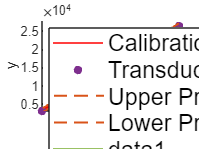

RMSE_quad_mm = Quad_gof_Rig.rmse;

if RMSE_quad_mm > RMSE_linear_mm
U_rig_mm = RMSE_quad_mm*2
Rig_fit_Data=feval(Quad_Rig_Fit,CForce_Rig_Def)
Rig_Up_Bound = Rig_fit_Data+U_rig_mm
Rig_Low_Bound= Rig_fit_Data-U_rig_mm

%Plot Data
plot(F_rig_N,Rig_fit_Data)
plot(F_rig_N,CForce_Rig_Def,'o')

%Plot Bounds
plot(F_rig_N,Rig_Up_Bound,'--')
plot(F_rig_N,Rig_Low_Bound,'--')

else
    U_rig_mm = RMSE_linear_mm*2
Rig_fit_Data=feval(Lin_Rig_fit,CForce_Rig_Def)
Rig_Up_Bound = Rig_fit_Data+U_rig_mm
Rig_Low_Bound= Rig_fit_Data-U_rig_mm

%Plot Data
plot(CForce_Rig_Def,Rig_fit_Data)
plot(CForce_Rig_Def,U_rig_mm,'o')

%Plot Bounds
plot(CForce_Rig_Def,Rig_Up_Bound,'--')
plot(CForce_Rig_Def,Rig_Low_Bound,'--')
end